str = input('Enter TS: ','s');
s = 'GOOGL_2006-01-01_to_2018-01-01.csv';
try
    q = '.csv';
    T = readtable(strcat(str, q))
    'Временной ряд был успешно загружен'
catch ME
    'Неправильно выбран временной ряд, проверьте корректность ввода'
    
end

ans = 'Неправильно выбран временной ряд, проверьте корректность ввода'


y = [1:100]';
y = y .^ 3;

y_real = y;

я

n_previous_days = 10;
[y, mx_y] = featureNormalizeZeroOne(y_real);
%y = y_real;
%Create time series features
[X,y] = timeSeriesFeatures(y,n_previous_days);



я

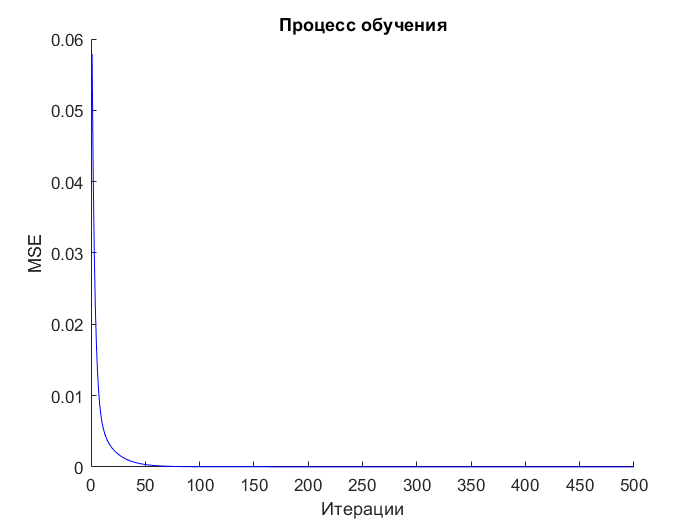

alpha = 0.1;            %0.1 learning rate
iterations = 500;       %num of iterations200
lambda = 0;            %regularisation parameter11 (3.2)

% Init Theta as zeroes with size of X
theta = zeros(size(X,2)+1, 1);
[theta, J_history] = gradientDescentMulti(X, y, theta, alpha, iterations, lambda);

plotData(1:size(J_history), J_history, 'Итерации','MSE','b');
hold on
title('Процесс обучения')
hold off

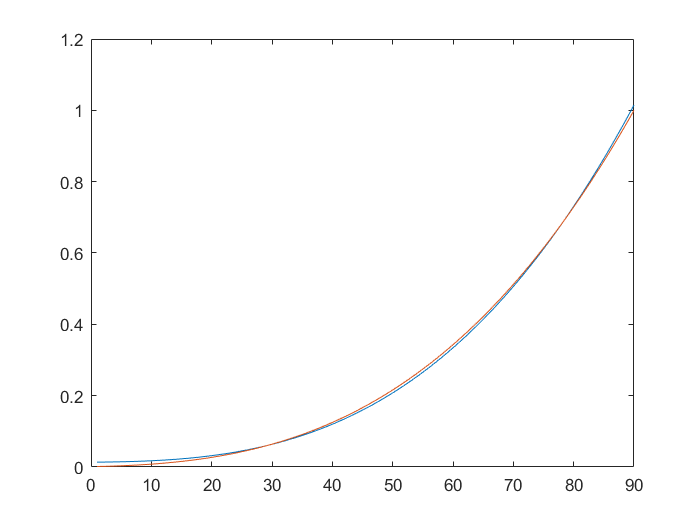

hyp = linPredict(X,theta);

plot(hyp);
hold on
plot(y);
hold off